# Video Processing with DMD - Application

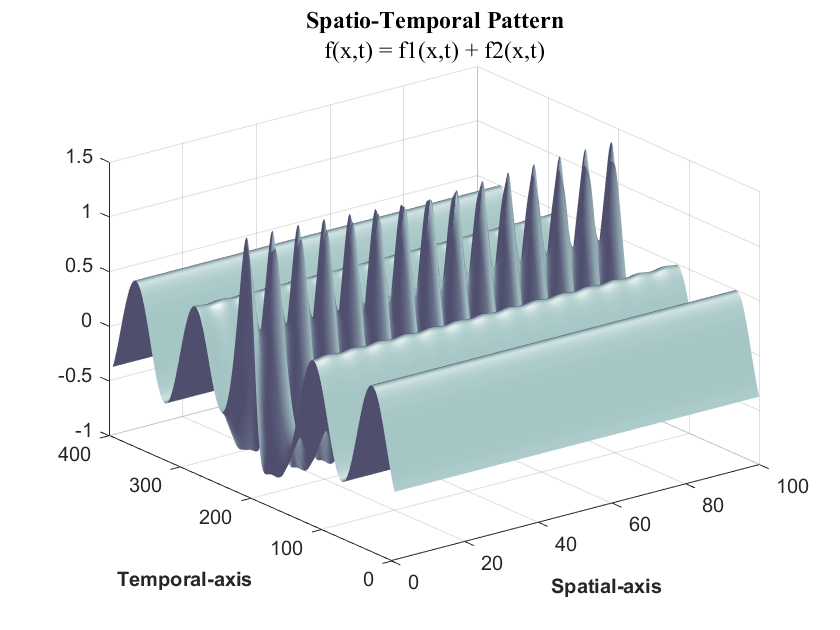

% Discretization of space and time
x = linspace(-15,15,400);
t = linspace(0,10*pi,100); 
dt = t(2) - t(1); 
[X_grid,T_grid] = meshgrid(x,t);

%% Creating spatio-temporal patterns f1 & f2
f1 = 0.5*cos(X_grid) .* (1+0*T_grid);  % time-independent!
f2 = (sech(X_grid).*tanh(X_grid)) .* (2*exp(1j*2.8*T_grid));

% Combining signals and making data matrix
f = (f1 + f2)'; 

figure(1);
surfl(real(f));
shading interp;
colormap bone;
xlabel('Spatial-axis','FontSize',10,'FontWeight','bold'); 
ylabel('Temporal-axis','FontSize',10,'FontWeight','bold');
title("Spatio-Temporal Pattern","f(x,t) = f1(x,t) + f2(x,t)",'FontName','times new roman','FontSize',12);

% Create data matrices for DMD
X1 = f(:,1:end-1);
X2 = f(:,2:end);

% Performing SVD and rank-50 truncation
r = 50; % rank truncation
[U, S, V] = svd(X1, 'econ');
Ur = U(:, 1:r);
Sr = S(1:r, 1:r);
Vr = V(:, 1:r);

% Build A_tilde and DMD Modes
A_tilde = Ur'*X2*Vr/Sr;

[eig_vec, eig_val] = eig(A_tilde);
Phi = X2*Vr/Sr*eig_vec;  % DMD Modes

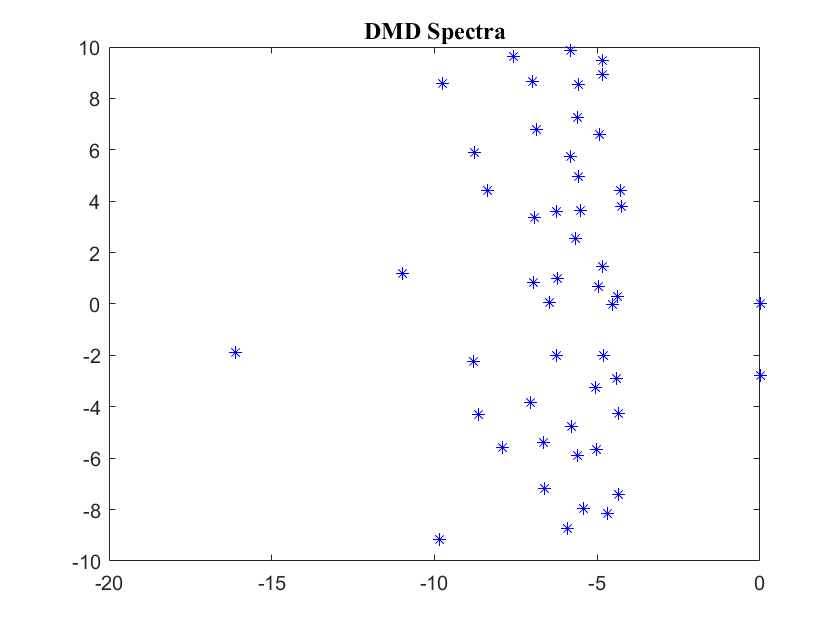

% DMD Spectra
lambda = diag(eig_val);
omega = log(lambda)/dt;

figure(2);
plot(omega, 'b*');
title('DMD Spectra','FontName','times new roman','FontSize',12);

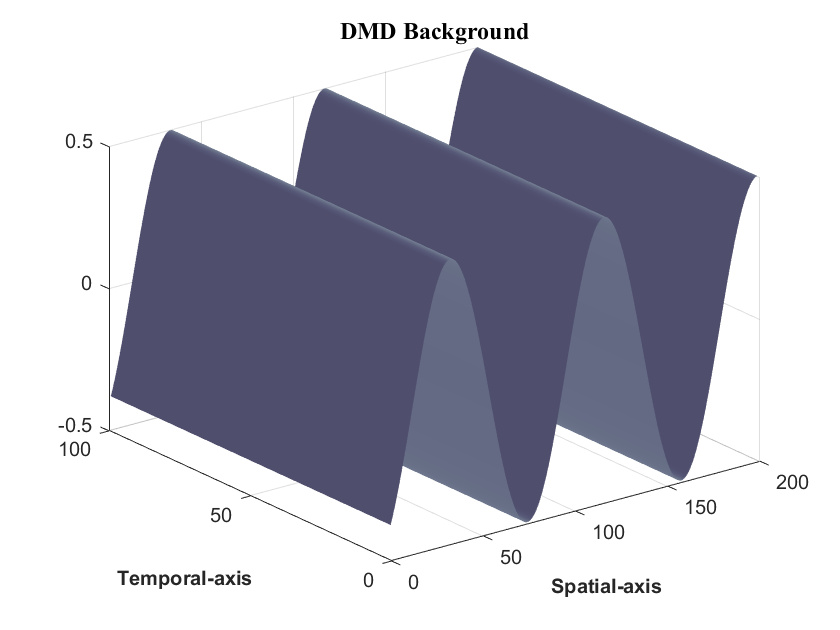

% Declaring fore-ground and background 
bg = find(abs(omega) < 1e-2);
fg = setdiff(1:r, bg);

omega_fg = omega(fg); % foreground
Phi_fg = Phi(:,fg); % DMD foreground modes

omega_bg = omega(bg); % background
Phi_bg = Phi(:,bg); % DMD background modes

% DMD Background
b = Phi_bg \ f(:, 1);
X_bg = zeros(numel(omega_bg), length(t));
for tt = 1:length(t)
    X_bg(:, tt) = b .* exp(omega_bg .* t(tt));
end
X_bg = Phi_bg * X_bg;
X_bg = X_bg(1:n,:);

figure(3);
surfl(real(X_bg'));
shading interp;
colormap bone;
xlabel('Spatial-axis','FontSize',10,'FontWeight','bold'); 
ylabel('Temporal-axis','FontSize',10,'FontWeight','bold');
title('DMD Background','FontName','times new roman','FontSize',12);

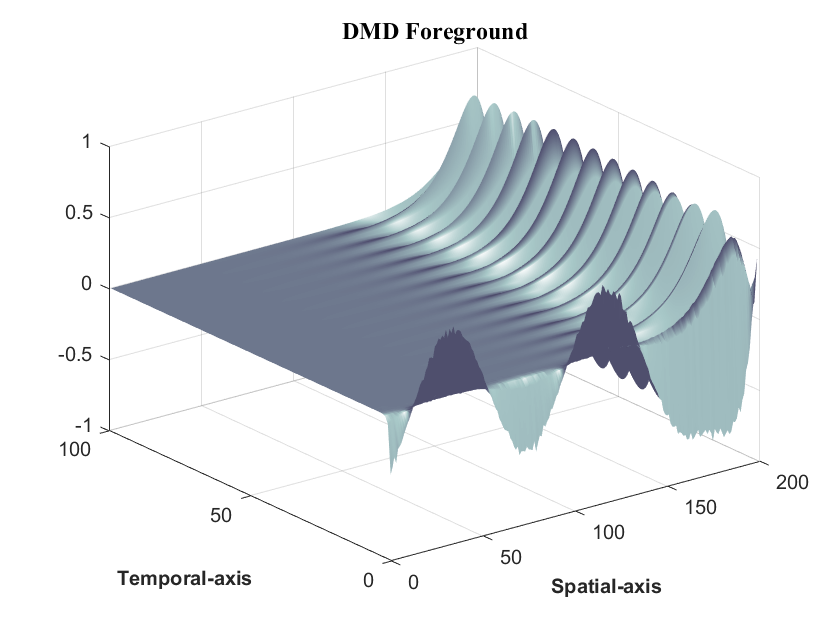

% DMD Foreground 
b = Phi_fg \ f(:, 1);
X_fg = zeros(numel(omega_fg), length(t));
for tt = 1:length(t)
    X_fg(:, tt) = b .* exp(omega_fg .* t(tt));
end
X_fg = Phi_fg * X_fg;
X_fg = X_fg(1:n,:);

figure(4);
surfl(real(X_fg')); 
shading interp;
colormap bone;
xlabel('Spatial-axis','FontSize',10,'FontWeight','bold'); 
ylabel('Temporal-axis','FontSize',10,'FontWeight','bold');
title('DMD Foreground','FontName','times new roman','FontSize',12);